# K-means clustering

clear;clc;

## Data Processing

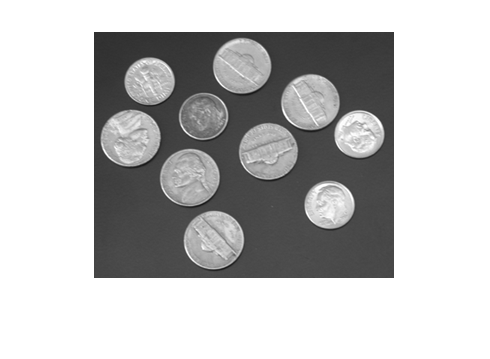

coins = imread('coins.png');
imshow(coins);

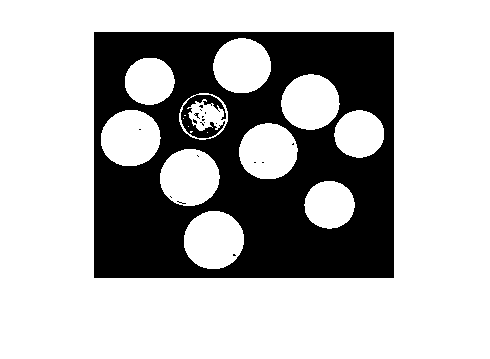

level = graythresh(coins);
coins = imbinarize(coins,level);
imshow(coins);

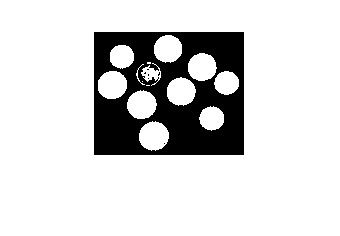

coins = imresize(coins, [round(size(coins,1)/2), round(size(coins,2)/2)]);
imshow(coins);

X_train = zeros(size(coins,1)*size(coins,2),3);
k = 1;
for i=1:size(coins,1)
    for j=1:size(coins,2)
        X_train(k,:) = [i j coins(i,j)*255];
        k = k+1;
    end
end

## Image Segmentation

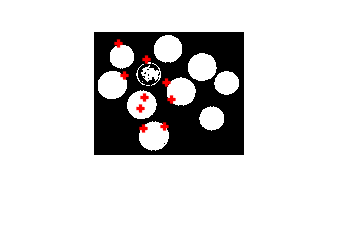

class_assign = zeros(size(X_train,1),1);
prev_class_assign = rand(size(X_train,1),1);
K = 10;
means = rand(K,size(X_train,2));
% shift = round(size(X_train,1)/K);
for i=1:K
    r = round(size(X_train,1)*rand(1,1));
    if r==0
        r = r+1;
    end
%     r = shift*i;    
    means(i,:) = X_train(r,:);
end

imshow(coins);
hold on;
for i=1:K
    plot(round(means(i,1)),round(means(i,2)), 'r+', 'MarkerSize', 5, 'LineWidth', 2);
end
hold off;

itr = 0;
max_itr = 50;
while sum(prev_class_assign==class_assign)<size(X_train,1)
    if itr>max_itr
%         break;
    end
    itr = itr + 1;
    disp(["Iteration " + num2str(itr)]);
    prev_class_assign = class_assign;
    J = zeros(K,1);
    for j=1:size(X_train,1)
        dists = zeros(K,1);
        for i=1:K
            dists(i,:) = norm(X_train(j,:)-means(i,:));
        end
        [dist,c] = min(dists);
        class_assign(j,:) = c;
        J(c) = J(c) + dist;
    end
    means = zeros(K,size(X_train,2));
    for j=1:size(X_train,1)
        for i=1:K
            if class_assign(j,:)==i
                means(i,:) = means(i,:) + X_train(j,:);
            end
        end
    end
    for i=1:K
        means(i,:) = means(i,:)/sum(class_assign==i);
    end
    disp("Cost J "+num2str(sum(J)));
end

Iteration 1


Cost J 555085.5978


Iteration 2


Cost J 473927.755


Iteration 3


Cost J 436861.6947


Iteration 4


Cost J 417270.9507


Iteration 5


Cost J 408210.1583


Iteration 6


Cost J 404307.8132


Iteration 7


Cost J 403030.6588


Iteration 8


Cost J 402323.2008


Iteration 9


Cost J 401708.2885


Iteration 10


Cost J 401089.9243


Iteration 11


Cost J 400457.7851


Iteration 12


Cost J 399806.925


Iteration 13


Cost J 398969.3217


Iteration 14


Cost J 397661.2941


Iteration 15


Cost J 395117.5643


Iteration 16


Cost J 391017.8496


Iteration 17


Cost J 386402.432


Iteration 18


Cost J 383759.0624


Iteration 19


Cost J 382823.9341


Iteration 20


Cost J 382504.0982


Iteration 21


Cost J 382414.0377


Iteration 22


Cost J 382385.0628


Iteration 23


Cost J 382373.321


Iteration 24


Cost J 382375.1248


Iteration 25


Cost J 382376.0281


Iteration 26


Cost J 382378.1578


Iteration 27


Cost J 382383.2647


Iteration 28


Cost J 382385.6471


Iteration 29


Cost J 382387.1269


Iteration 30


Cost J 382393.3792


Iteration 31


Cost J 382398.1496


Iteration 32


Cost J 382397.208


Iteration 33


Cost J 382395.6108


## Results

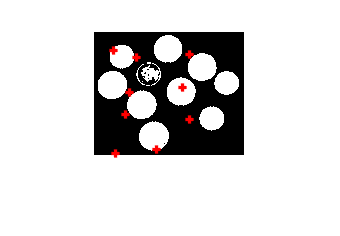

imshow(coins);
hold on;
for i=1:K
    plot(round(means(i,1)),round(means(i,2)), 'r+', 'MarkerSize', 5, 'LineWidth', 2);
end
hold off;